# RVC2: chapter 4

format compact
close all
clear
clc

## 4.1.1 Car-like mobile robots

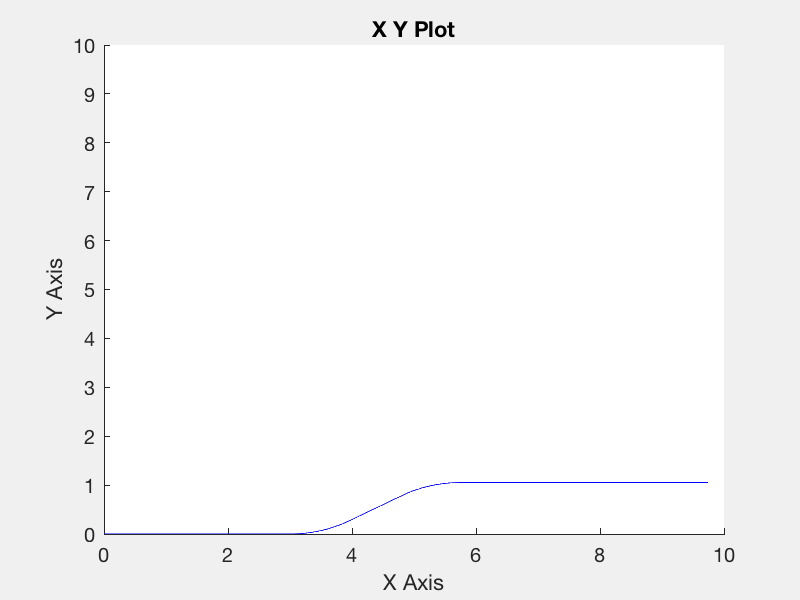

out =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sl_lanechange

% we can't push the simulate button on the Simulink model from this script so we simulate it
out = sim('sl_lanechange')  


out

out =   Simulink.SimulationOutput:

                      t: [504x1 double] 
                      y: [504x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


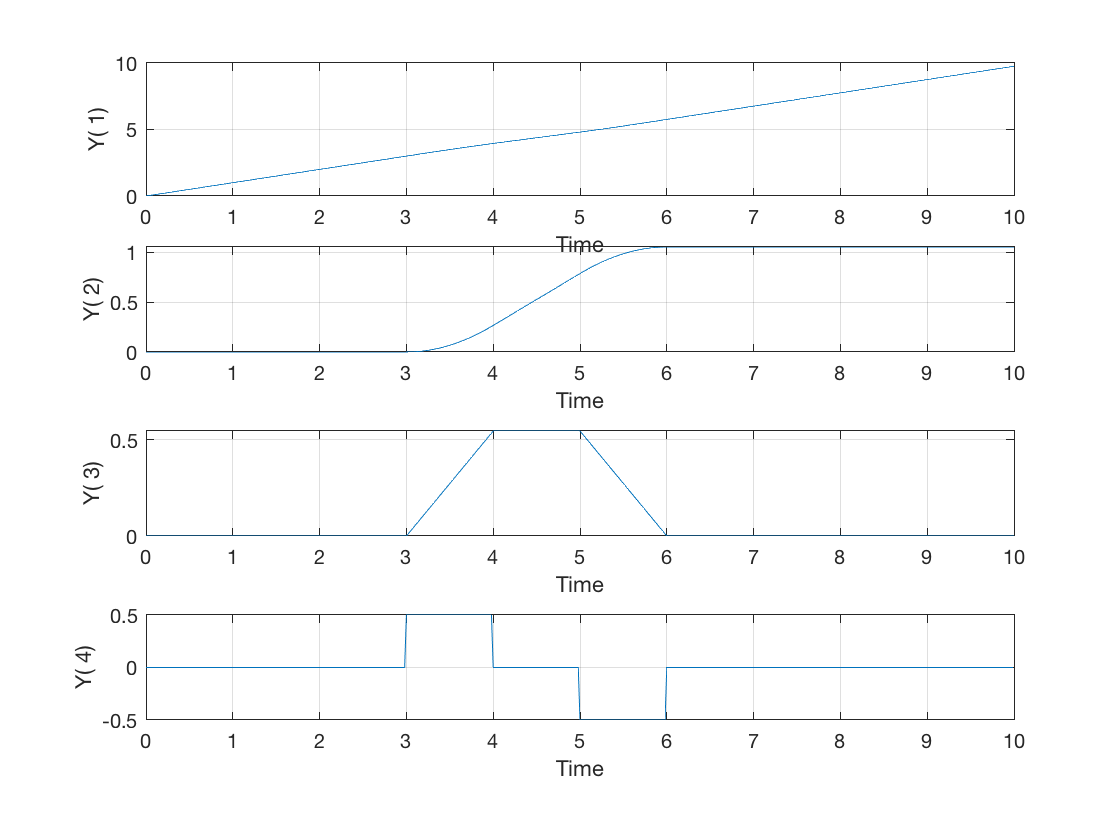


t = out.get('t'); q = out.get('y');

figure
mplot(t, q)

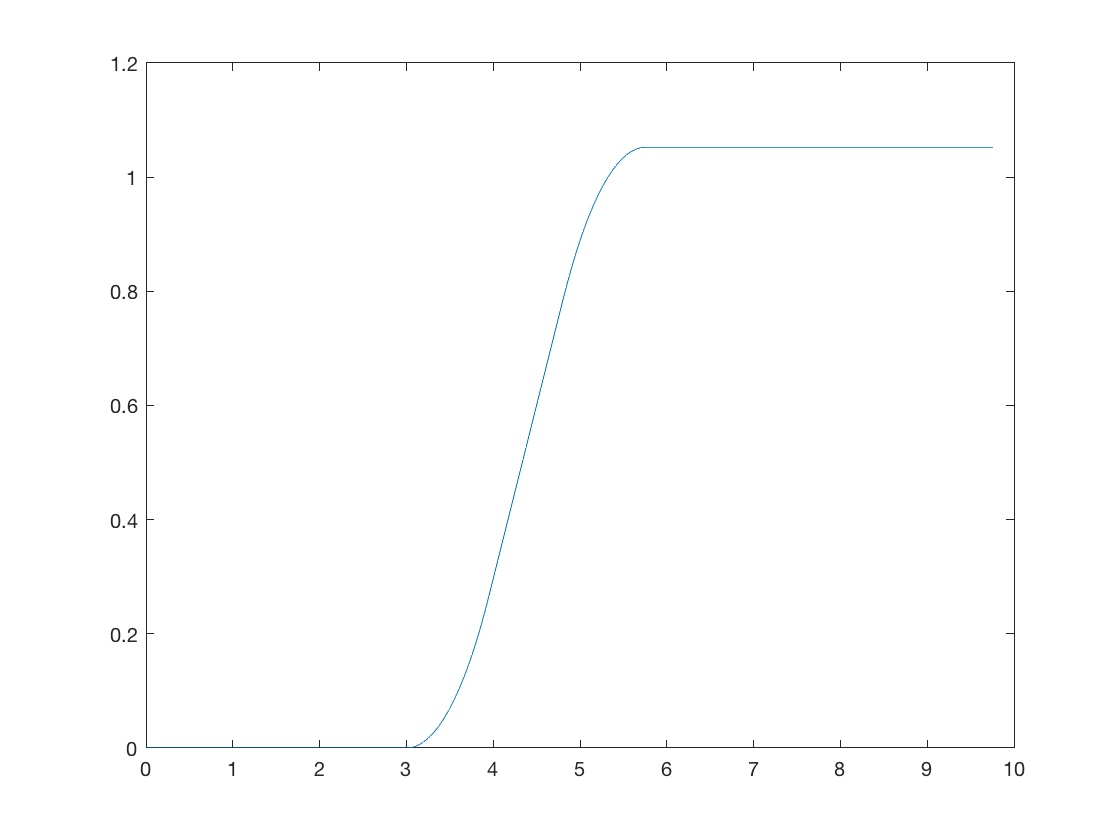

clf
plot(q(:,1), q(:,2))

## 4.1.1.1 Moving to a point

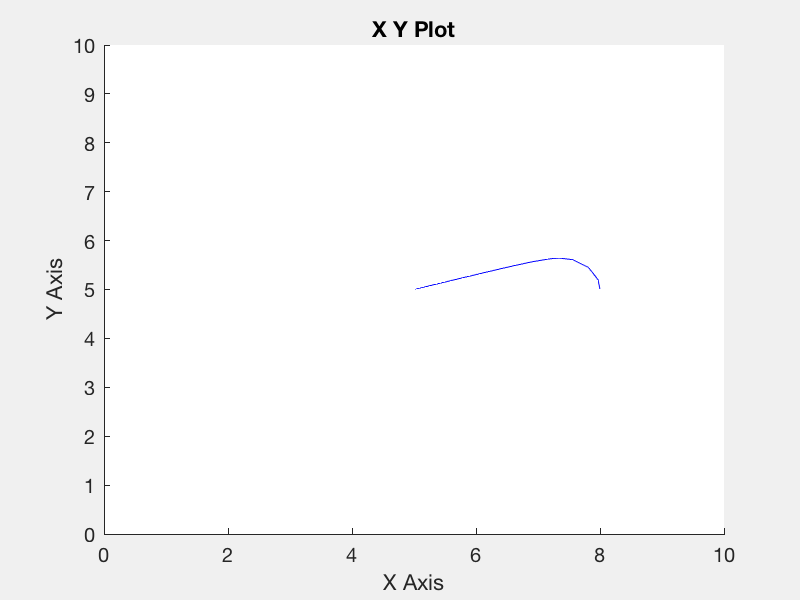

bdclose('all');

sl_drivepoint

xg = [5 5];

x0 = [8 5 pi/2];

r = sim('sl_drivepoint');

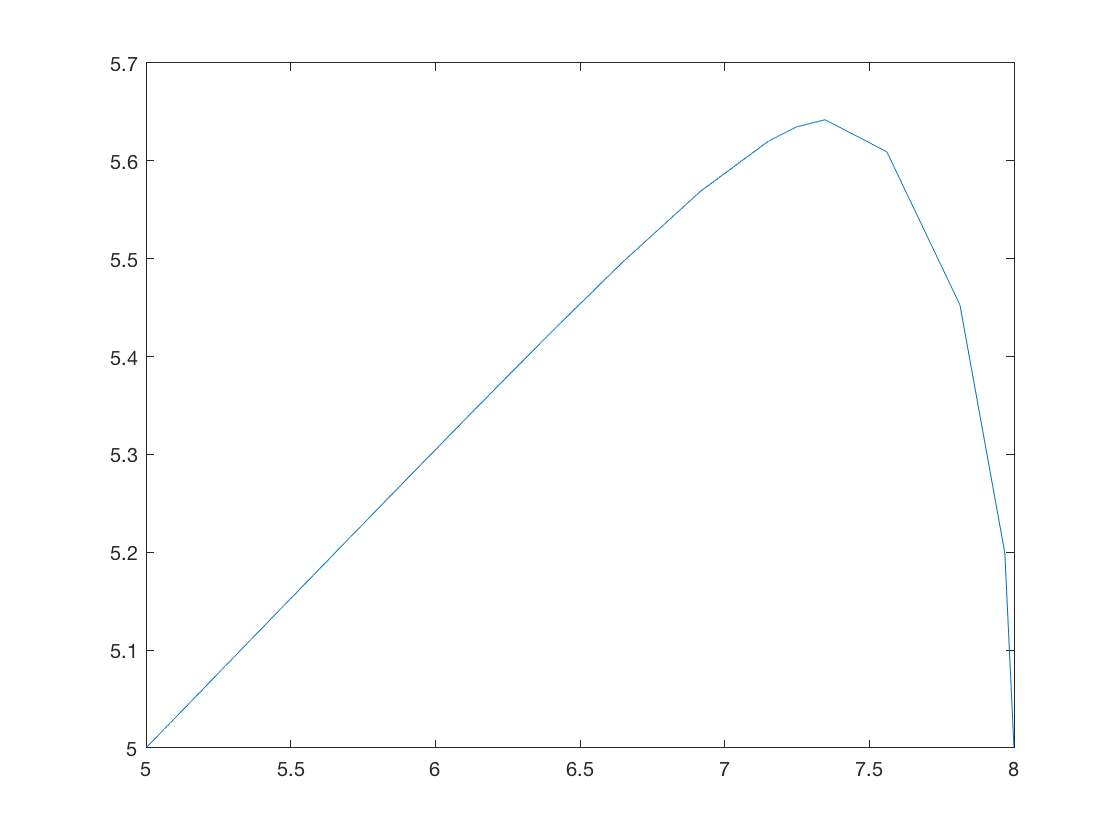


q = r.find('y');

plot(q(:,1), q(:,2));

## 4.1.1.2 Following a line

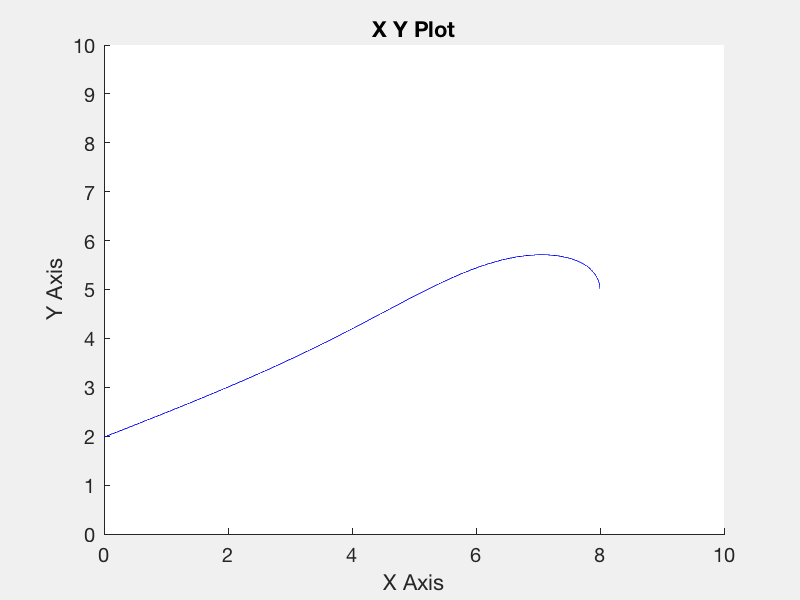

bdclose('all');

sl_driveline

L = [1 -2 4];

x0 = [8 5 pi/2];

r = sim('sl_driveline');

## 4.1.1.3 Following a trajectory

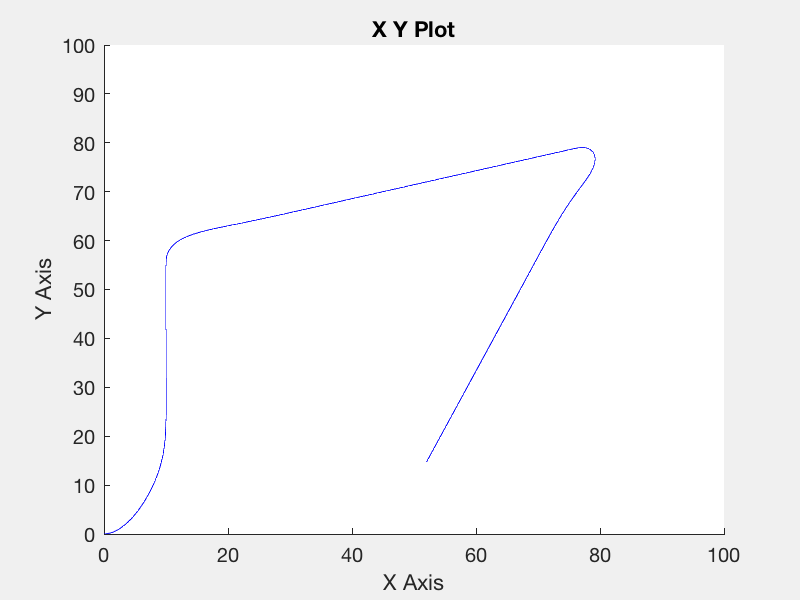

r =   Simulink.SimulationOutput:

                      t: [773x1 double] 
                      y: [773x6 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


bdclose('all');

sl_pursuit

r = sim('sl_pursuit')

## 4.1.1.4  Moving to a pose

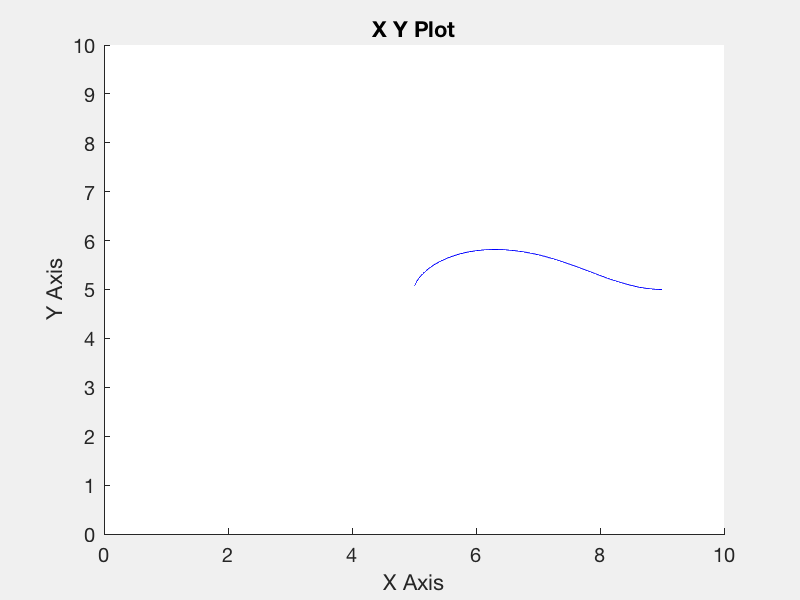

alpha -3.141593, beta 3.141593
going backwards


bdclose('all');

sl_drivepose

xg = [5 5 pi/2];

x0 = [9 5 0];

r = sim('sl_drivepose');

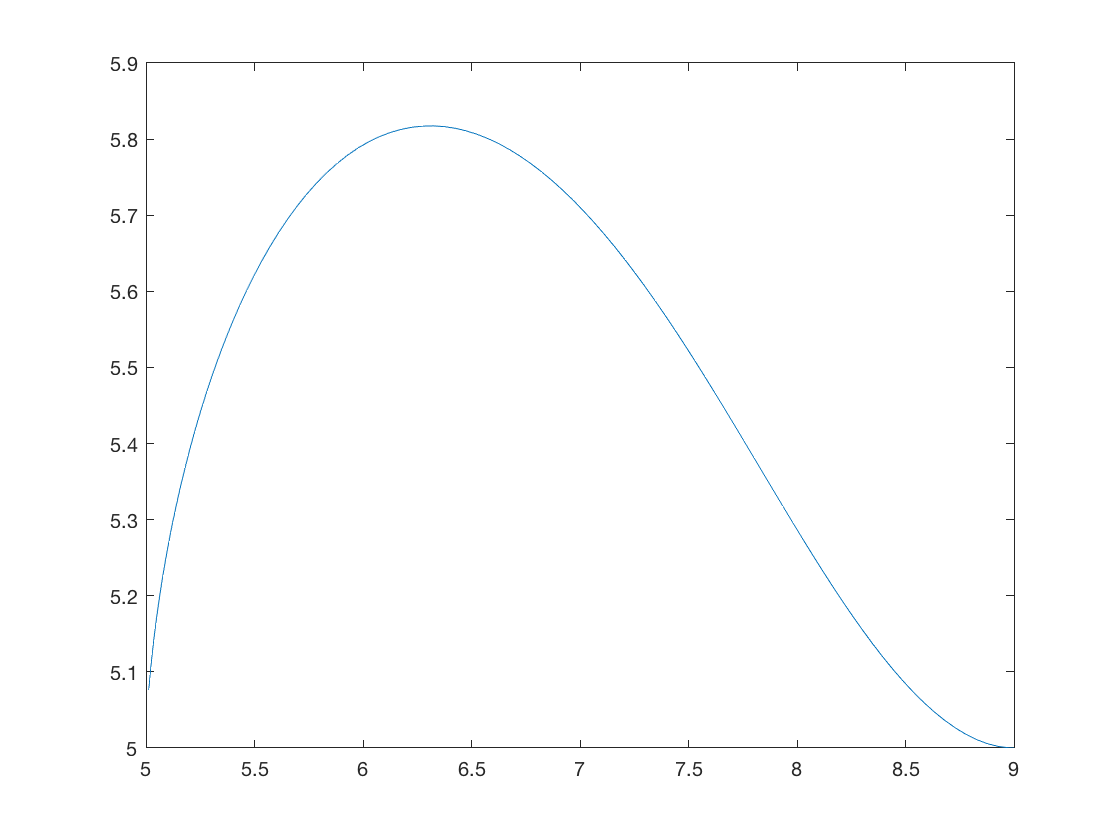


q = r.find('y');
clf
plot(q(:,1), q(:,2));

## 4.2 Flying robots

bdclose('all');

sl_quadrotor

mdl_quadrotor

sim('sl_quadrotor');


about result

result [double] : 2412x16 (308.7 kB)


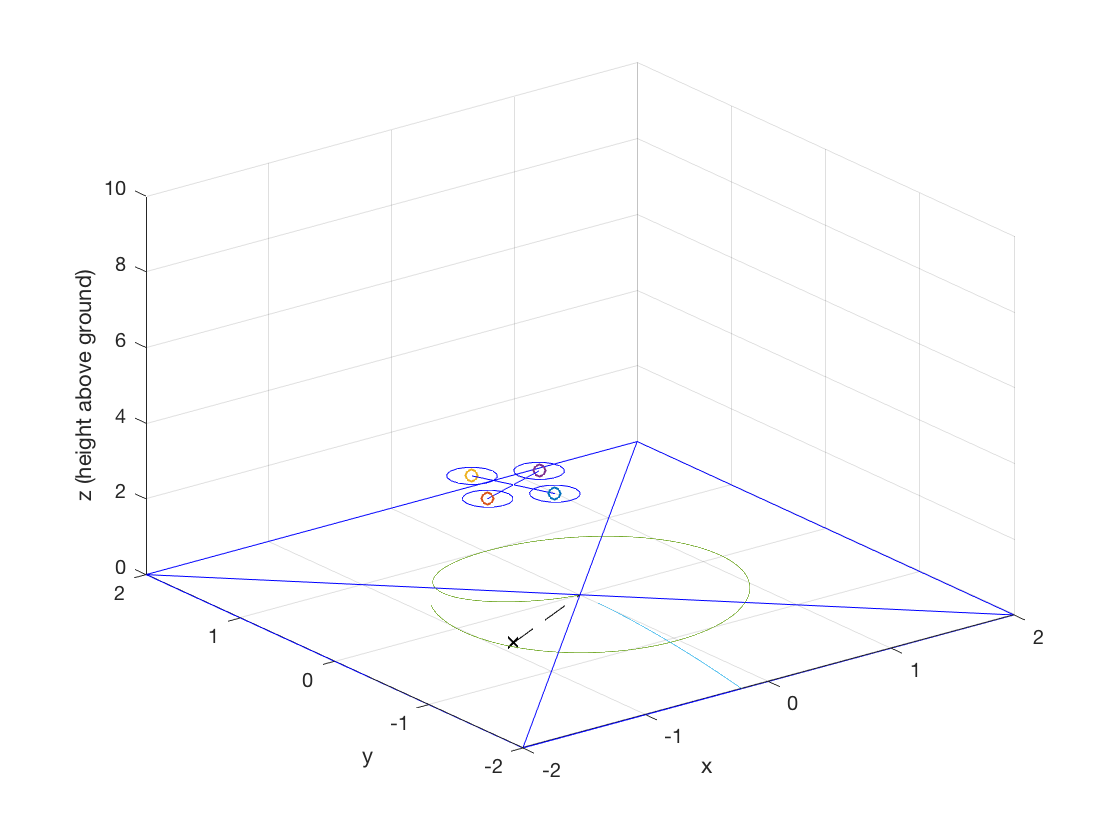


plot(result(:,1), result(:,2:3));

bdclose('all')